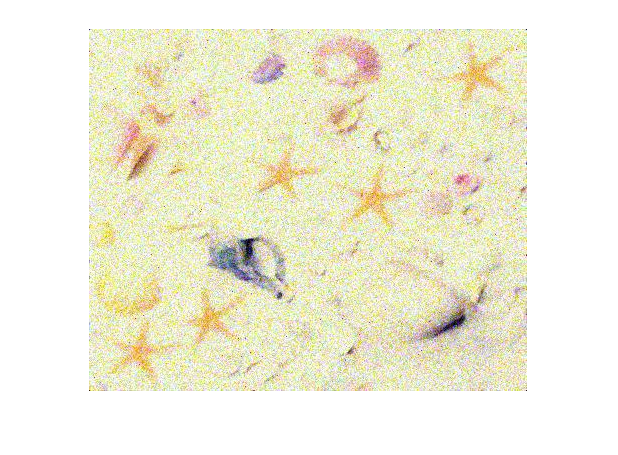

im = imread("images\starfish_noise7.jpg");
imshow(im)

% noisy = imnoise(im, 'salt & pepper', 0.5);
% noisy = imnoise(im, 'gaussian');
noisy = im;
% imshow(noisy)
% title("Noisy");

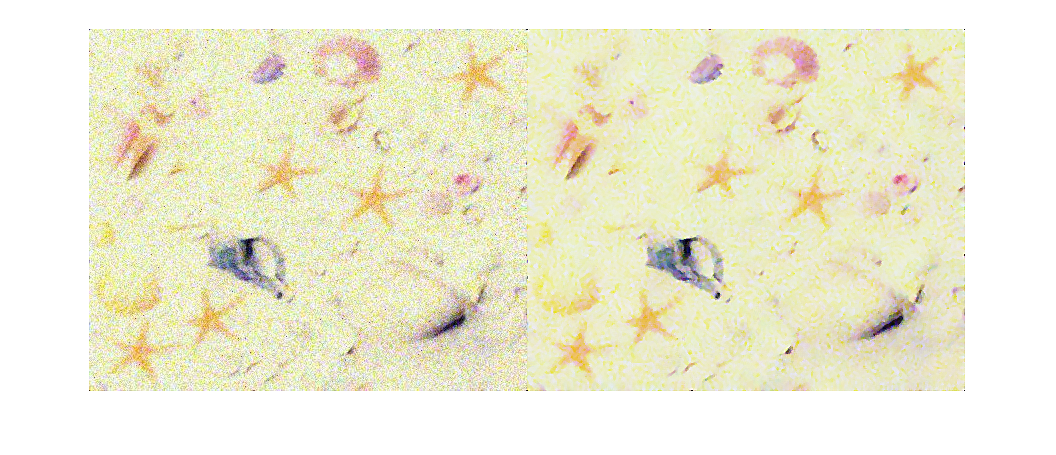

filtered = DenoiseG(noisy); % Artificial/loss of detail but colour ok.
% filtered = medfilt3(noisy); % Better detail retention but colour incorrect.
imshowpair(im, filtered, 'montage')

CountImpulsePixels(filtered)

ans = 101

function [ch1, ch2, ch3] = CountImpulsePixels(im)
[ch1, ch2, ch3] = imsplit(im);
ch1 = length(find(ch1 == 0 | ch1 == 255));
ch2 = length(find(ch2 == 0 | ch2 == 255));
ch3 = length(find(ch3 == 0 | ch3 == 255));
end

function imP = DenoiseG(im)
dims = ndims(im);

if (dims == 2)
    imP = DenoiseG2D(im);
elseif (dims == 3)
    imP = DenoiseG3D(im);
else
    error("Unsupported number of dimensions. Expected a 2D or 3D array.");
end
end


function imP = DenoiseG2D(im)
imP = imnlmfilt(im);
% % imP = imfilter(im, ones(3)/9);
% imP = wiener2(im,[5 5]);
% % imP = wiener2(im,[3 3]);
% imP = imgaussfilt(imP);
imP = medfilt2(imP);
imP = imsharpen(imP, 'amount', 2);
end


function imP = DenoiseG3D(im)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
dnCh1 = DenoiseG2D(ch1);
dnCh2 = DenoiseG2D(ch2);
dnCh3 = DenoiseG2D(ch3);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
end
